Testbed - Throughput profile estimation for INDIS 2023

   Nagi Rao

   raons@ornl.gov

   started: June 30, 2022

   modified: June 30, 2022; August 10, 2023; September 26, 2023

**Reference**:

Nageswara S. V. Rao. 2023. Experimental Study of TCP Throughput Profiles and Dynamics Over Dedicated Connections. In Workshops of The International Conference on High Performance Computing, Network, Storage, and Analysis (SC-W 2023), November 12–17, 2023, Denver, CO, USA. ACM, New York, NY, USA, 8 pages. https://doi.org/10.1145/3624062.3624589

addpath('C:\Users\3nr\OneDrive - Oak Ridge National Laboratory\work_dir\matlab_dir');


n_measure=10;

rtt=[ 1 12 22 29 49 75 93 105 150 183 366 ]; % 0 is 1
num_rtt=length(rtt);
rtt_g=[ 1 13 24 32 47 60 81 91 114 130 170 202 225 248 287 319 376 ]; % 0 is 1
num_rtt_g=length(rtt_g);


testbed_rtt=[ 0 12 22 29 49 75 93 105 150 183 366 ];
num_testbed_rtt=length(testbed_rtt);
testbed_rtt_g=[ 1 13 24 32 47 60 81 91 114 130 170 202 225 248 287 318 376 ];
testbed_rtt_g1=[ 1 13 24 32 47 60 81 91 114 130 170 202 225 248 287 319 376 ];
num_testbed_rtt_g=length(rtt_g);

date_set=[ '0 ms  '; '11 ms '; '22 ms '; '29 ms '; '49 ms '; '75 ms '; '93 ms ';  '105 ms'; '150 ms'; '183 ms'; '366 ms'] ;
celldate = cellstr(date_set);

date_set1=[ '0  '; '11 '; '22 '; '29 '; '49 '; '75 '; '93 ';  '105'; '150'; '183'; '366'] ;
celldate1 = cellstr(date_set1);

date_set_g=[ '0 ms  '; '13 ms '; '24 ms '; '32 ms '; '47 ms '; '60 ms '; '81 ms '; '91 ms '; ...
    '114 ms'; '130 ms'; '170 ms'; '202 ms'; '225 ms'; '248 ms'; '287 ms'; '319 ms'; '376 ms'] ;
celldate_g = cellstr(date_set_g);

date_set_g1=[ '0  '; '13 '; '24 '; '32 '; '47 '; '60 '; '81 '; '91 '; ...
    '114'; '130'; '170'; '202'; '225'; '248'; '287'; '319'; '376'] ;
celldate_g1 = cellstr(date_set_g1);

tau(1)=1;
tau(2)=13;
tau(3)=24;
tau(4)=32;
tau(5)=47;
tau(6)=60;
tau(7)=81;
tau(8)=91;
tau(9)=114;
tau(10)=130;
tau(11)=170;
tau(12)=202;
tau(13)=225;
tau(14)=248;
tau(15)=287;
tau(16)=319;
tau(17)=379;
n_tau=17;

cc_turbo=turbo(12);

dir_name='C:\Users\3nr\OneDrive - Oak Ridge National Laboratory\work_dir\INDIS\INDIS2023\datasets\throughput'

dir_name = 'C:\Users\3nr\OneDrive - Oak Ridge National Laboratory\work_dir\INDIS\INDIS2023\datasets\throughput'

#### No Loss: BBR,  CUBIC - HTCP

dir_name='C:\Users\3nr\OneDrive - Oak Ridge National Laboratory\work_dir\INDIS\INDIS2023\datasets\throughput'

dir_name = 'C:\Users\3nr\OneDrive - Oak Ridge National Laboratory\work_dir\INDIS\INDIS2023\datasets\throughput'

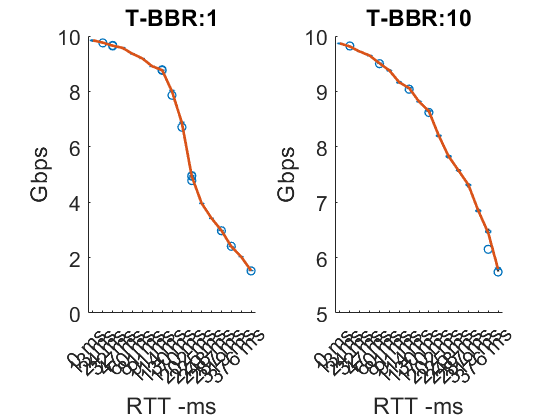


file_name='iperf3_tcp_log_q1_c1_10gige_c2_q2_bbr_updated_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_bbr1_single,testbed_bbr1_ten,testbed_bbr1_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_bbr1_single,testbed_bbr1_ten,celldate_g,celldate_g,'T-BBR:1','T-BBR:10');

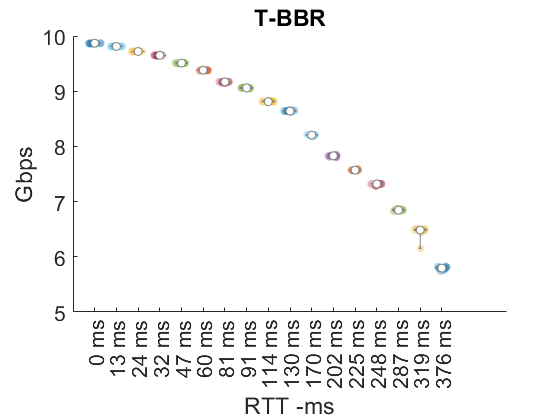

plot_violine(40,testbed_bbr1_ten,celldate_g,'T-BBR');

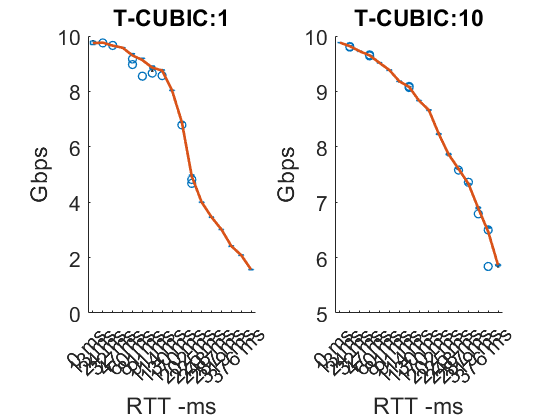


file_name='iperf3_tcp_log_q1_c1_10gige_c2_q2_cubic_updated_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_cubic1_single,testbed_cubic1_ten,testbed_cubic1_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_cubic1_single,testbed_cubic1_ten,celldate_g,celldate_g,'T-CUBIC:1','T-CUBIC:10');

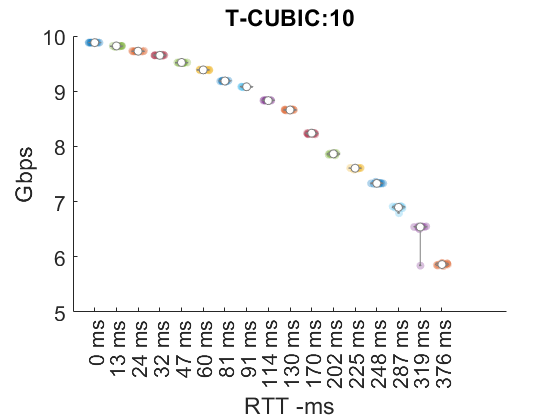

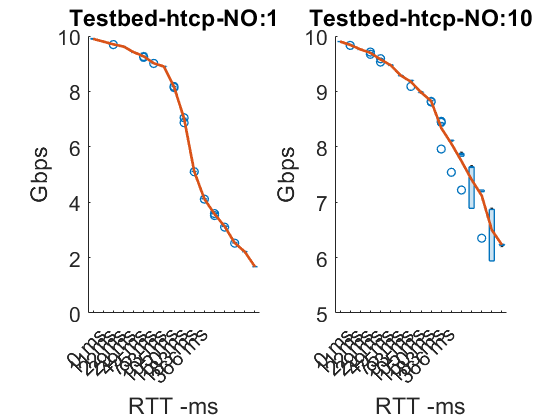

plot_violine(40,testbed_cubic1_ten,celldate_g,'T-CUBIC:10');

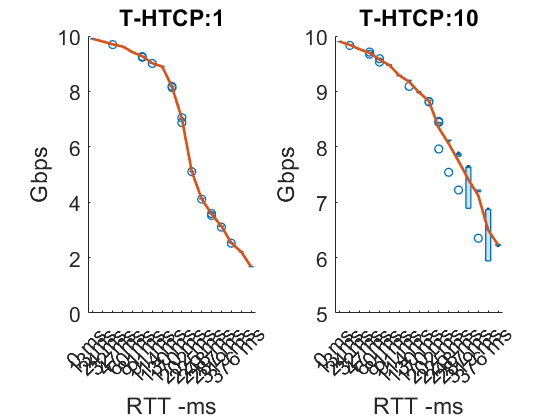


file_name='iperf3_tcp_log_q1_c1_10gige_c2_q2_htcp_updated_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_htcp1_single,testbed_htcp1_ten,testbed_htcp1_ten_mean]=read_data_testbed_txt(testbed_rtt_g,testbed_dir_name);

figure(140); clf reset
plot_box_pair(40,testbed_htcp1_single,testbed_htcp1_ten,celldate_g,celldate_g,'T-HTCP:1','T-HTCP:10');

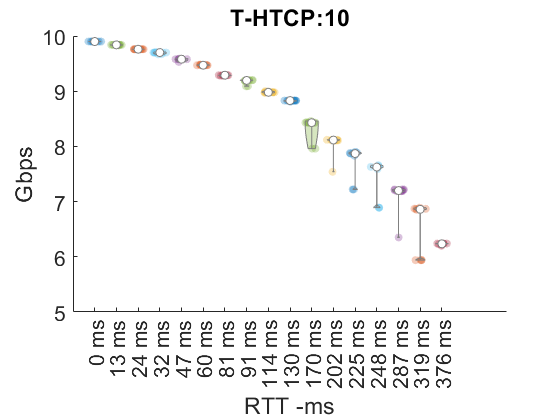

plot_violine(40,testbed_htcp1_ten,celldate_g,'T-HTCP:10');

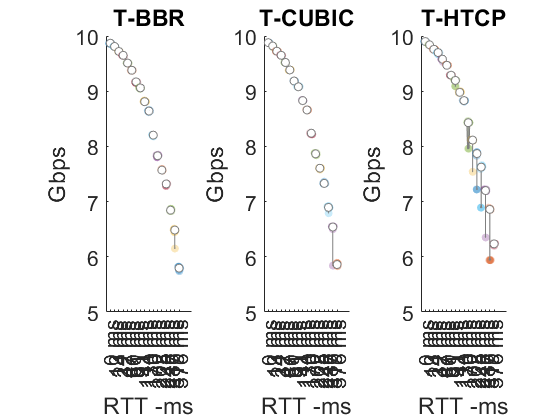


figure(240); clf reset
plot_violine_3(240,testbed_bbr1_ten,testbed_cubic1_ten,testbed_htcp1_ten,...
celldate_g,celldate_g,celldate_g,...
'T-BBR','T-CUBIC','T-HTCP');

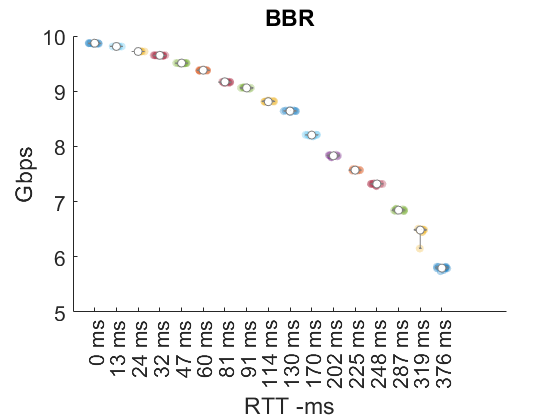


figure(240); clf reset
plot_violine(240,testbed_bbr1_ten,celldate_g,'BBR');

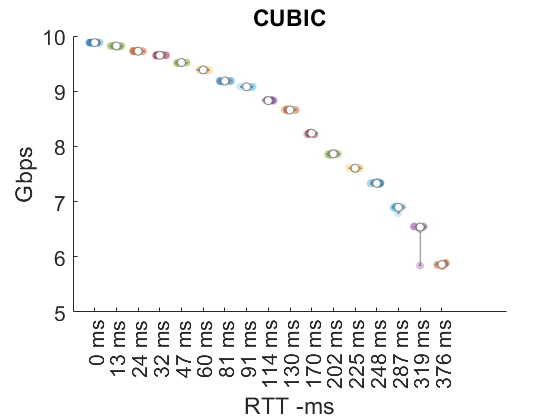


figure(240); clf reset
plot_violine(240,testbed_cubic1_ten,celldate_g,'CUBIC');

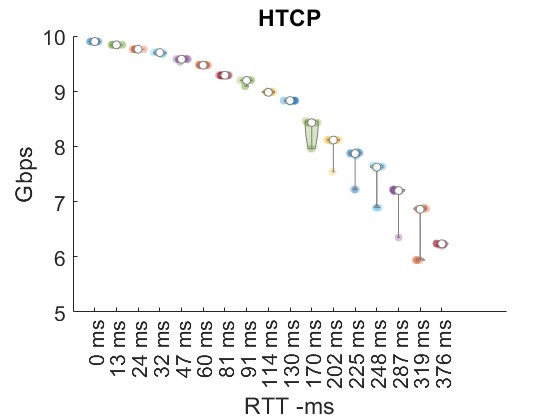


figure(240); clf reset
plot_violine(240,testbed_htcp1_ten,celldate_g,'HTCP');

#### 1 in 100000: BBR,  CUBIC - HTCP: Q1-C1-10GigE-C2-Q2 - 9K MTU

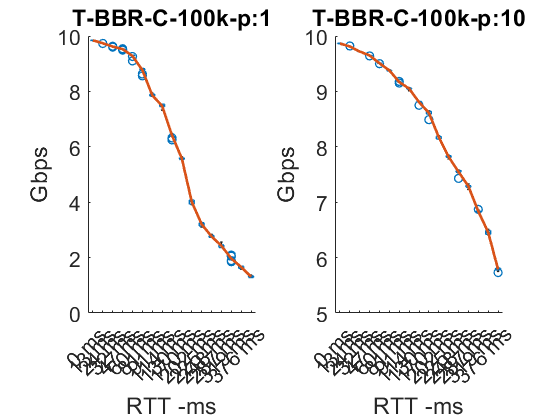


file_name='iperf3_tcp_log_q1_c1_10gige_limit_100000_dist_1_periodic_c2_q2_bbr_updated_9k_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_bbr_j_100000_p_single,testbed_bbr_j_100000_p_ten,testbed_bbr_j_1000000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_bbr_j_100000_p_single,testbed_bbr_j_100000_p_ten,celldate_g,celldate_g,'T-BBR-C-100k-p:1','T-BBR-C-100k-p:10');

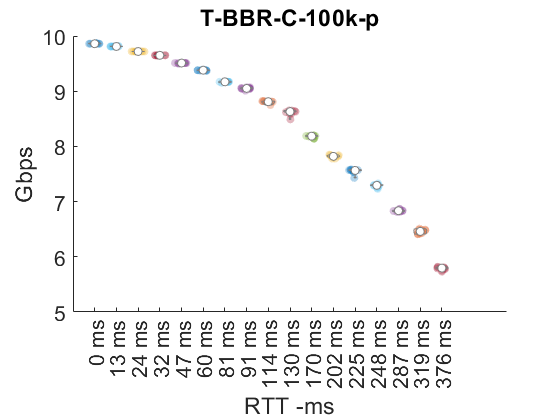

plot_violine(40,testbed_bbr_j_100000_p_ten,celldate_g,'T-BBR-C-100k-p');

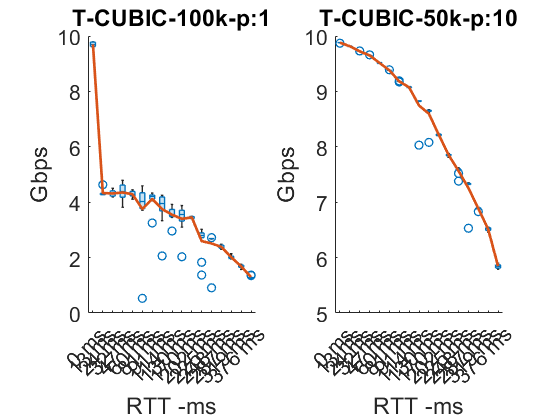


file_name='iperf3_tcp_log_q1_c1_10gige_limit_100000_dist_1_periodic_c2_q2_cubic_updated_9k_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_cubic_j_100000_p_single,testbed_cubic_j_100000_p_ten,testbed_cubic_j_100000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_cubic_j_100000_p_single,testbed_cubic_j_100000_p_ten,celldate_g,celldate_g,'T-CUBIC-100k-p:1','T-CUBIC-50k-p:10');

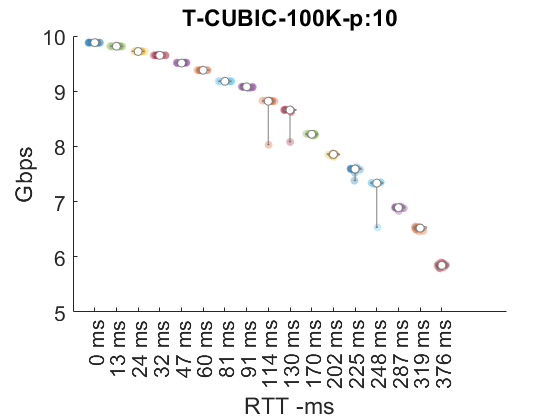

plot_violine(40,testbed_cubic_j_100000_p_ten,celldate_g,'T-CUBIC-100K-p:10');

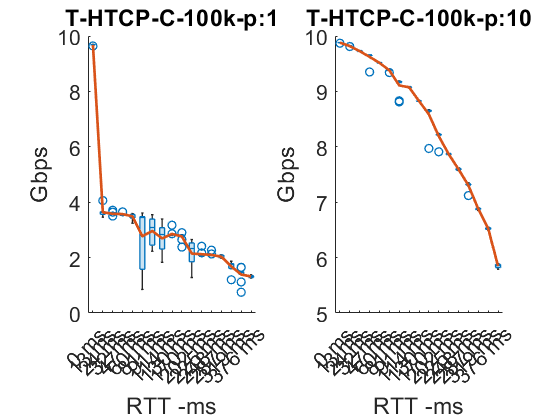


file_name='iperf3_tcp_log_q1_c1_10gige_limit_100000_dist_1_periodic_c2_q2_htcp_updated_9k_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_htcp_j_100000_p_single,testbed_htcp_j_100000_p_ten,testbed_htcp_j_100000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_htcp_j_100000_p_single,testbed_htcp_j_100000_p_ten,celldate_g,celldate_g,'T-HTCP-C-100k-p:1','T-HTCP-C-100k-p:10');

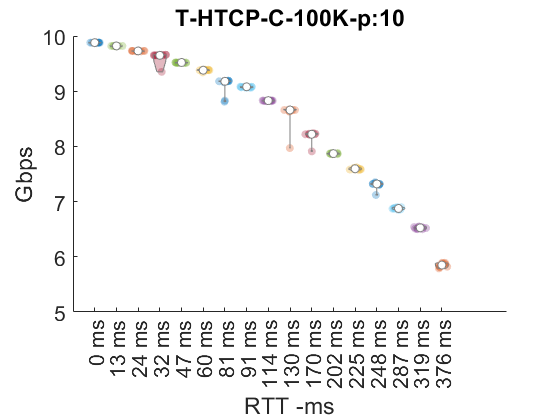

plot_violine(40,testbed_htcp_j_100000_p_ten,celldate_g,'T-HTCP-C-100K-p:10');

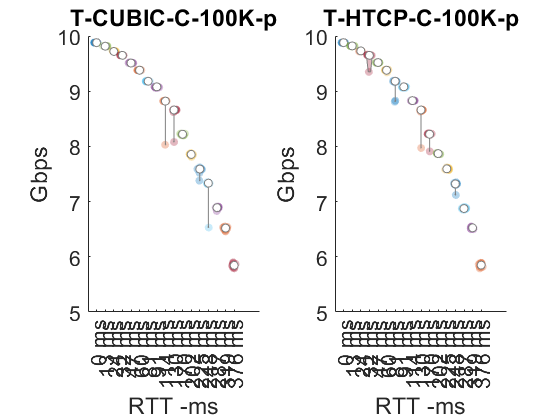


figure(240); clf reset
plot_violine_pair(240,testbed_cubic_j_100000_p_ten,testbed_htcp_j_100000_p_ten,...
celldate_g,celldate_g,...
'T-CUBIC-C-100K-p','T-HTCP-C-100K-p');

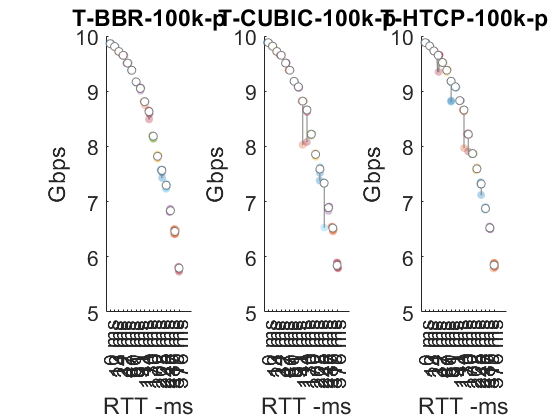


figure(240); clf reset
plot_violine_3(240,testbed_bbr_j_100000_p_ten,testbed_cubic_j_100000_p_ten,testbed_htcp_j_100000_p_ten,...
celldate_g,celldate_g,celldate_g,...
'T-BBR-100k-p','T-CUBIC-100k-p','T-HTCP-100k-p');

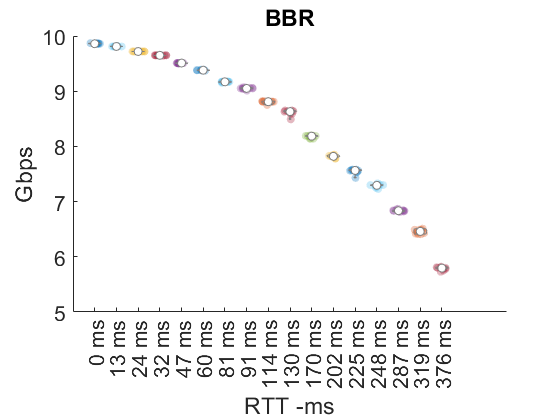


figure(240); clf reset
plot_violine(240,testbed_bbr_j_100000_p_ten,celldate_g,'BBR');

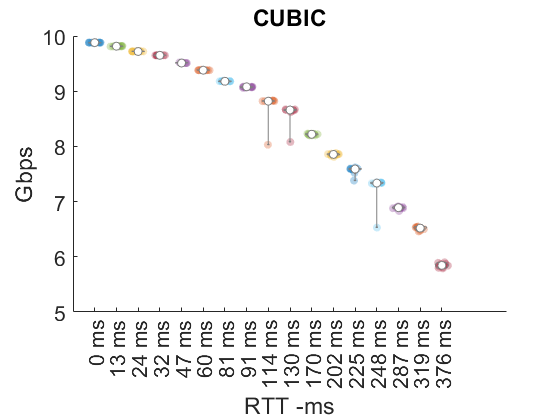


figure(240); clf reset
plot_violine(240,testbed_cubic_j_100000_p_ten,celldate_g,'CUBIC');

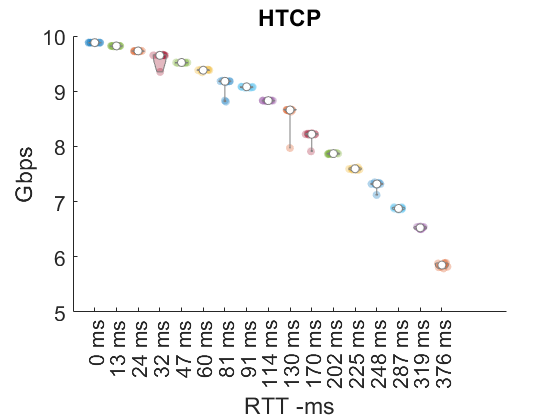


figure(240); clf reset
plot_violine(240,testbed_htcp_j_100000_p_ten,celldate_g,'HTCP');

#### 1 in 50000: BBR,  CUBIC - HTCP: Q1-C1-10GigE-C2-Q2: 9K MTU

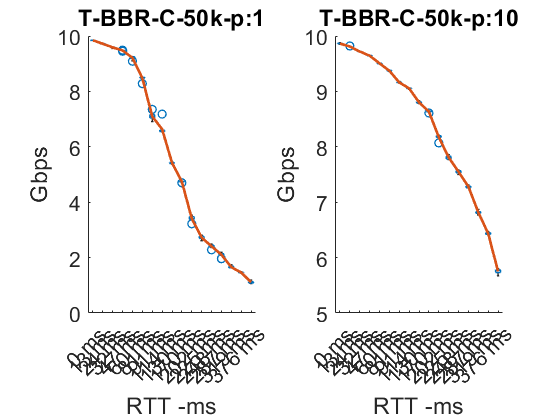


file_name='iperf3_tcp_log_q1_c1_10gige_limit_50000_dist_1_periodic_c2_q2_bbr_updated_9k_results\';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_bbr_j_50000_p_single,testbed_bbr_j_50000_p_ten,testbed_bbr_j_500000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_bbr_j_50000_p_single,testbed_bbr_j_50000_p_ten,celldate_g,celldate_g,'T-BBR-C-50k-p:1','T-BBR-C-50k-p:10');

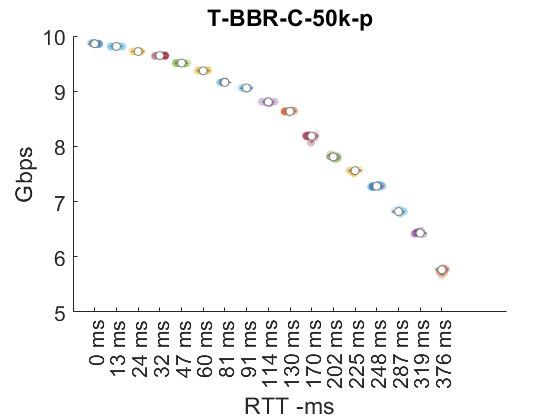

plot_violine(40,testbed_bbr_j_50000_p_ten,celldate_g,'T-BBR-C-50k-p');

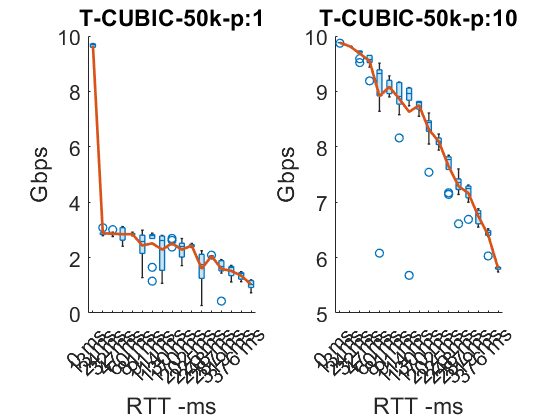


file_name='iperf3_tcp_log_q1_c1_10gige_limit_50000_dist_1_periodic_c2_q2_cubic_updated_9k_results\';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_cubic_j_50000_p_single,testbed_cubic_j_50000_p_ten,testbed_cubic_j_50000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_cubic_j_50000_p_single,testbed_cubic_j_50000_p_ten,celldate_g,celldate_g,'T-CUBIC-50k-p:1','T-CUBIC-50k-p:10');

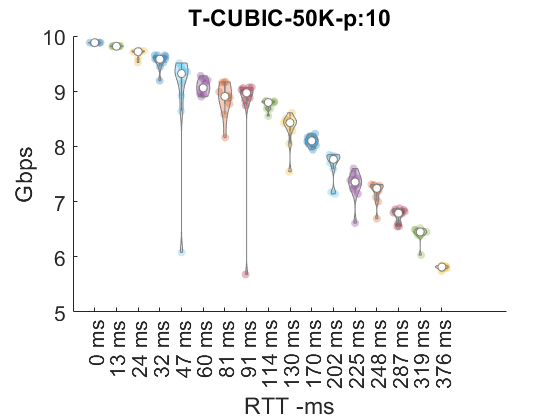

plot_violine(40,testbed_cubic_j_50000_p_ten,celldate_g,'T-CUBIC-50K-p:10');

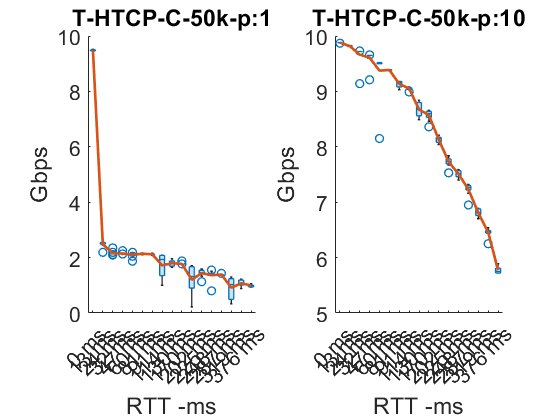


file_name='iperf3_tcp_log_q1_c1_10gige_limit_50000_dist_1_periodic_c2_q2_htcp_updated_9k_results\';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_htcp_j_50000_p_single,testbed_htcp_j_50000_p_ten,testbed_htcp_j_50000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_htcp_j_50000_p_single,testbed_htcp_j_50000_p_ten,celldate_g,celldate_g,'T-HTCP-C-50k-p:1','T-HTCP-C-50k-p:10');

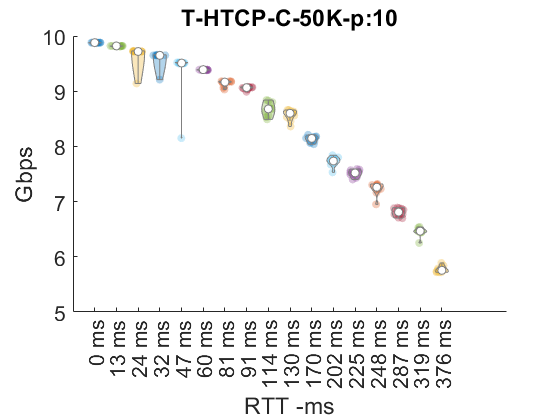

plot_violine(40,testbed_htcp_j_50000_p_ten,celldate_g,'T-HTCP-C-50K-p:10');

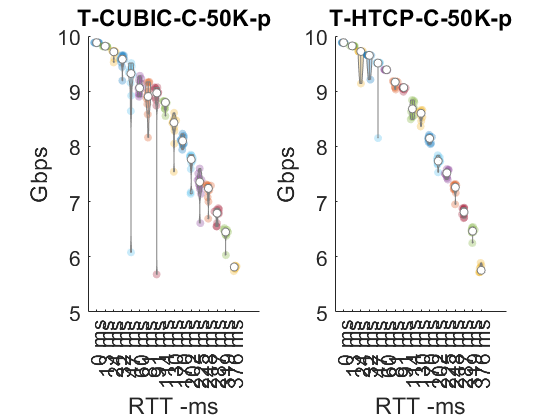


figure(240); clf reset
plot_violine_pair(240,testbed_cubic_j_50000_p_ten,testbed_htcp_j_50000_p_ten,...
celldate_g,celldate_g,...
'T-CUBIC-C-50K-p','T-HTCP-C-50K-p');

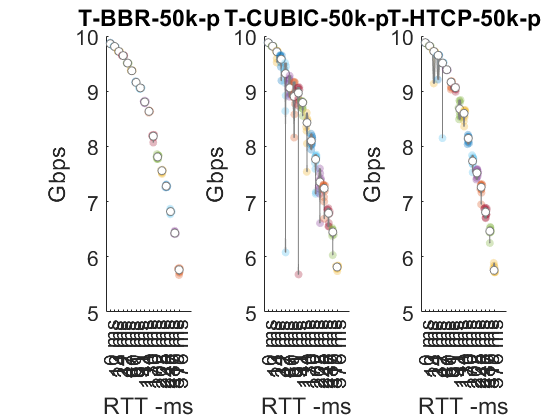


figure(240); clf reset
plot_violine_3(240,testbed_bbr_j_50000_p_ten,testbed_cubic_j_50000_p_ten,testbed_htcp_j_50000_p_ten,...
celldate_g,celldate_g,celldate_g,...
'T-BBR-50k-p','T-CUBIC-50k-p','T-HTCP-50k-p');

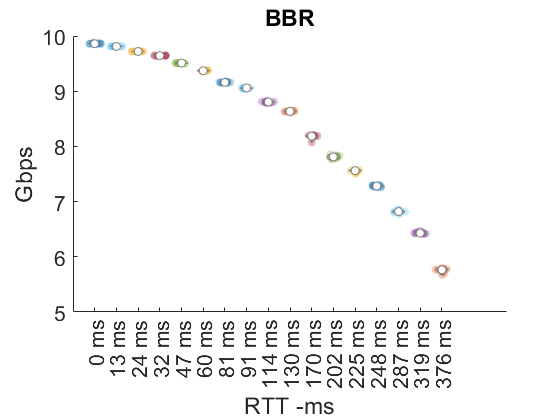


figure(240); clf reset
plot_violine(240,testbed_bbr_j_50000_p_ten,celldate_g,'BBR');

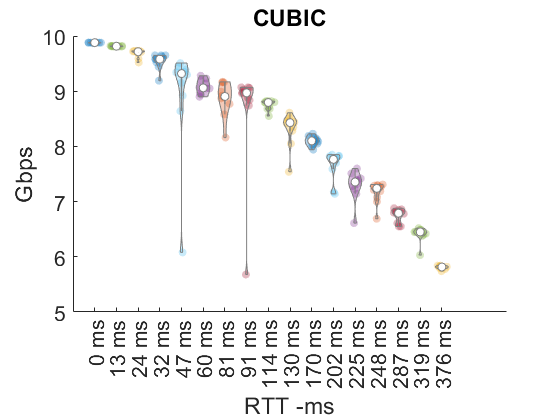


figure(240); clf reset
plot_violine(240,testbed_cubic_j_50000_p_ten,celldate_g,'CUBIC');

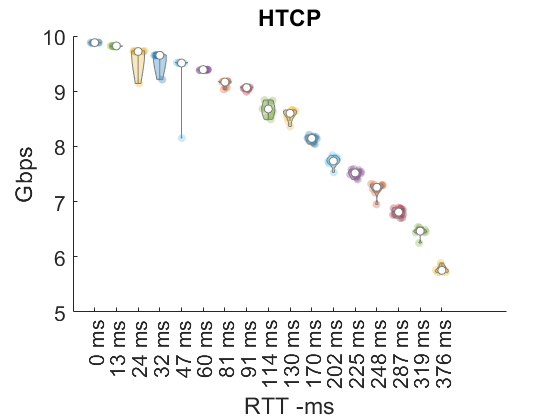


figure(240); clf reset
plot_violine(240,testbed_htcp_j_50000_p_ten,celldate_g,'HTCP');

#### 1 in 25000: BBR,  CUBIC - HTCP: Q1-C1-10GigE-C2-Q2: 9K MTU periodic

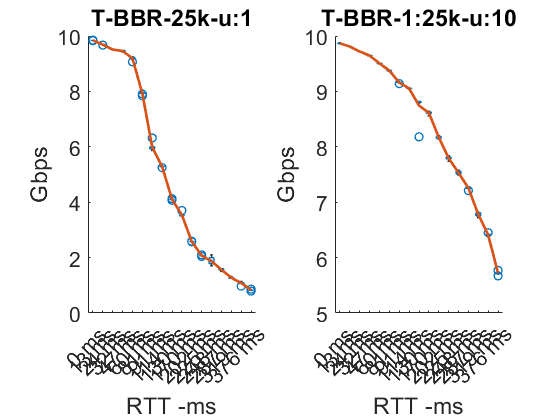

file_name='iperf3_tcp_log_q1_c1_10gige_limit_25000_dist_1_periodic_c2_q2_bbr_updated_9k_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_bbr_g_25000_p_single,testbed_bbr_g_25000_p_ten,testbed_bbr_g_25000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_bbr_g_25000_p_single,testbed_bbr_g_25000_p_ten,celldate_g,celldate_g,'T-BBR-25k-u:1','T-BBR-1:25k-u:10');

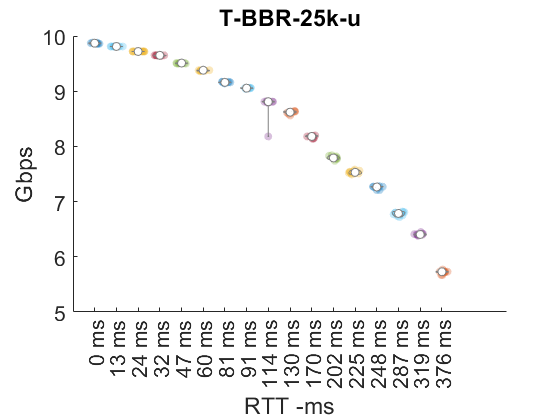

plot_violine(40,testbed_bbr_g_25000_p_ten,celldate_g,'T-BBR-25k-u');

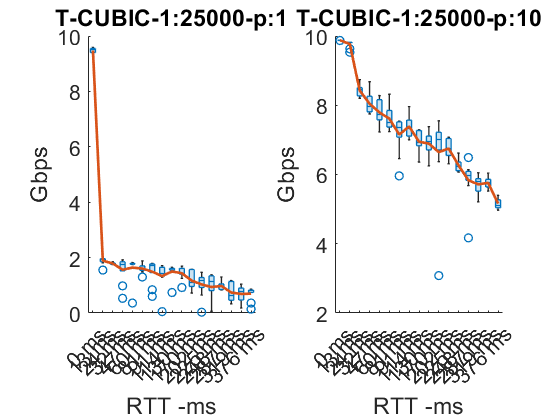


file_name='iperf3_tcp_log_q1_c1_10gige_limit_25000_dist_1_periodic_c2_q2_cubic_updated_9k_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_cubic_g_25000_p_single,testbed_cubic_g_25000_p_ten,testbed_cubic_g_25000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_cubic_g_25000_p_single,testbed_cubic_g_25000_p_ten,celldate_g,celldate_g,'T-CUBIC-1:25000-p:1','T-CUBIC-1:25000-p:10');

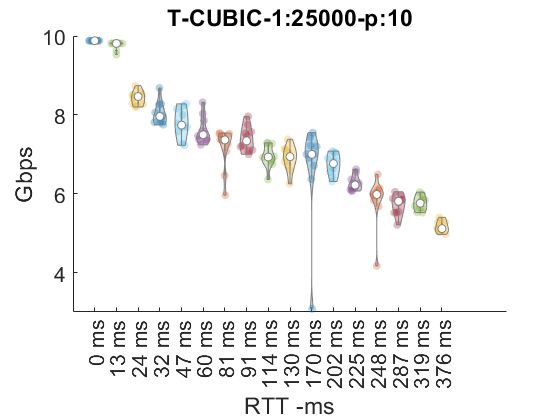

plot_violine(40,testbed_cubic_g_25000_p_ten,celldate_g,'T-CUBIC-1:25000-p:10');

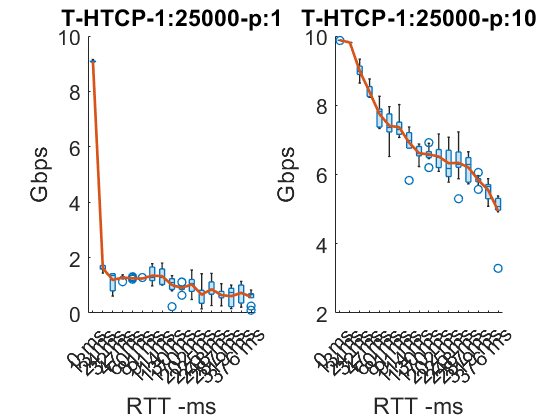


file_name='iperf3_tcp_log_q1_c1_10gige_limit_25000_dist_1_periodic_c2_q2_htcp_updated_9k_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_htcp_g_25000_p_single,testbed_htcp_g_25000_p_ten,testbed_htcp_g_25000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_htcp_g_25000_p_single,testbed_htcp_g_25000_p_ten,celldate_g,celldate_g,'T-HTCP-1:25000-p:1','T-HTCP-1:25000-p:10');

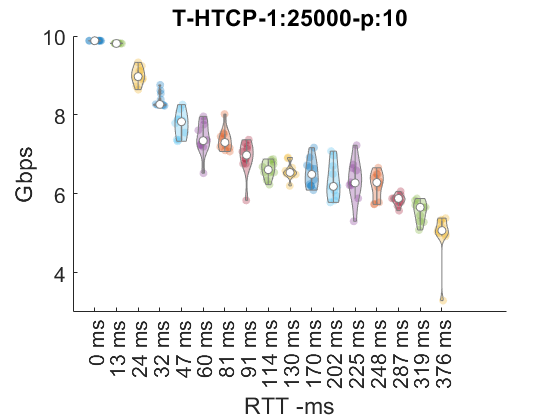

plot_violine(40,testbed_htcp_g_25000_p_ten,celldate_g,'T-HTCP-1:25000-p:10');

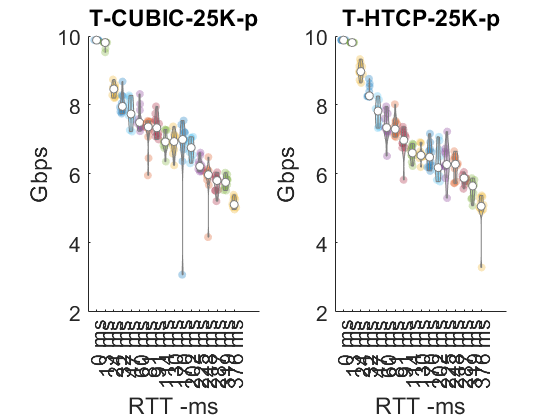


figure(240); clf reset
plot_violine_pair(240,testbed_cubic_g_25000_p_ten,testbed_htcp_g_25000_p_ten,...
celldate_g,celldate_g,...
'T-CUBIC-25K-p','T-HTCP-25K-p');

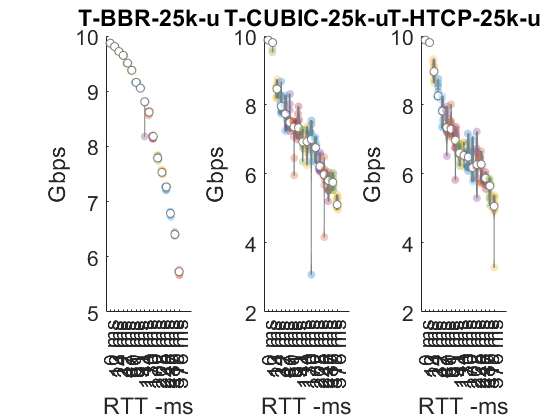


figure(240); clf reset
plot_violine_3(240,testbed_bbr_g_25000_p_ten,testbed_cubic_g_25000_p_ten,testbed_htcp_g_25000_p_ten,...
celldate_g,celldate_g,celldate_g,...
'T-BBR-25k-u','T-CUBIC-25k-u','T-HTCP-25k-u');

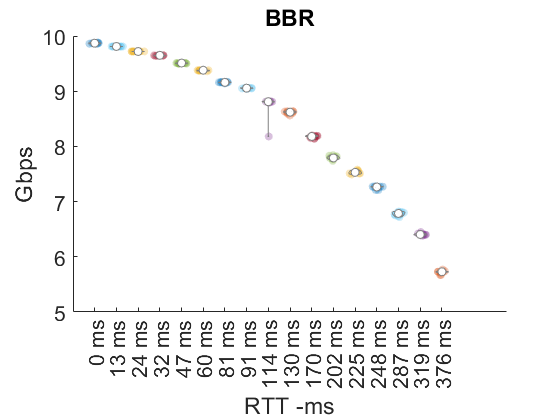


figure(240); clf reset
plot_violine(240,testbed_bbr_g_25000_p_ten,celldate_g,'BBR');

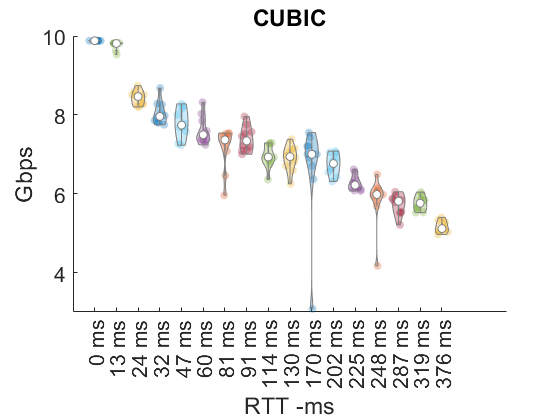


figure(240); clf reset
plot_violine(240,testbed_cubic_g_25000_p_ten,celldate_g,'CUBIC');

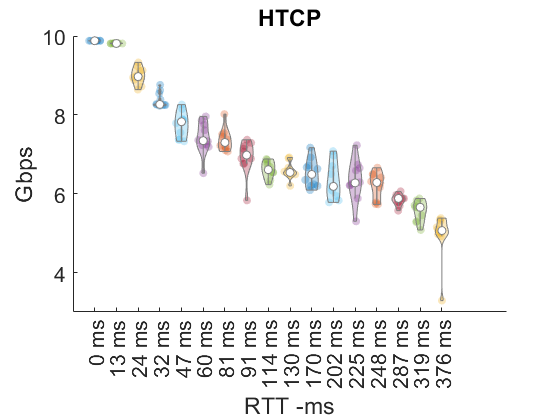


figure(240); clf reset
plot_violine(240,testbed_htcp_g_25000_p_ten,celldate_g,'HTCP');

#### 1 in 25000: BBR,  CUBIC - HTCP: Q1-C1-10GigE-C2-Q2: 9K MTU uniform

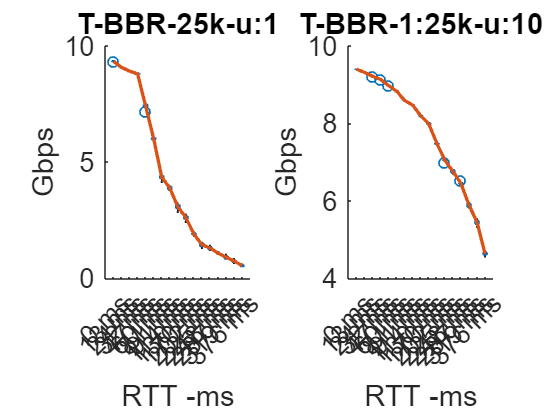

file_name='iperf3_tcp_log_q1_10gige_limit_25000_dist_4_uniform_q2_bbr_updated_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_bbr_g_25000_p_single,testbed_bbr_g_25000_p_ten,testbed_bbr_g_25000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_bbr_g_25000_p_single,testbed_bbr_g_25000_p_ten,celldate_g,celldate_g,'T-BBR-25k-u:1','T-BBR-1:25k-u:10');

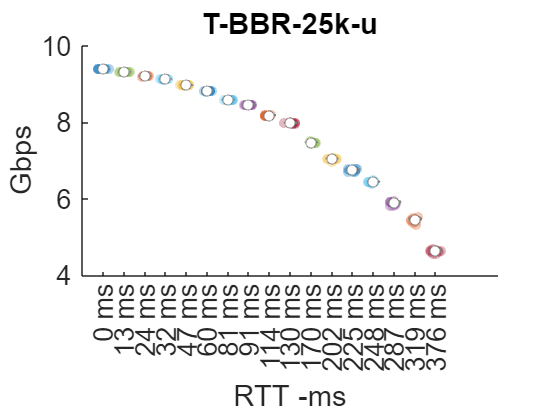

plot_violine(40,testbed_bbr_g_25000_p_ten,celldate_g,'T-BBR-25k-u');

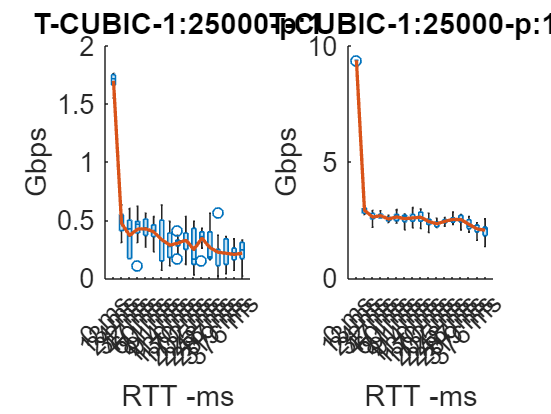


file_name='iperf3_tcp_log_q1_10gige_limit_25000_dist_4_uniform_q2_cubic_updated_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_cubic_g_25000_p_single,testbed_cubic_g_25000_p_ten,testbed_cubic_g_25000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_cubic_g_25000_p_single,testbed_cubic_g_25000_p_ten,celldate_g,celldate_g,'T-CUBIC-1:25000-p:1','T-CUBIC-1:25000-p:10');

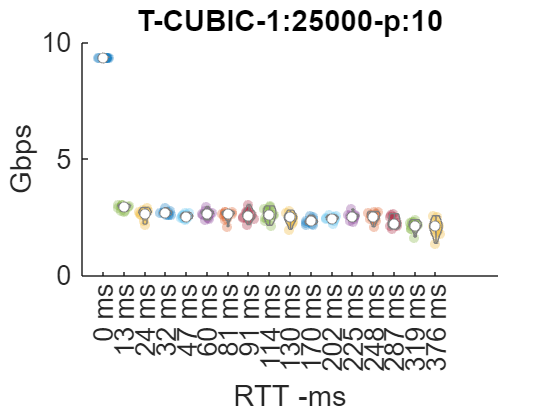

plot_violine(40,testbed_cubic_g_25000_p_ten,celldate_g,'T-CUBIC-1:25000-p:10');

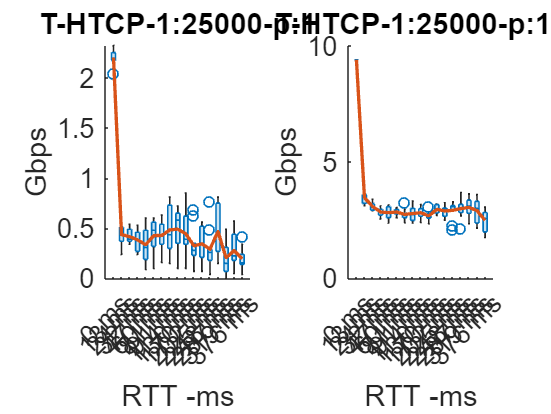


file_name='iperf3_tcp_log_q1_10gige_limit_37500_dist_4_uniform_q2_htcp_updated_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_htcp_g_25000_p_single,testbed_htcp_g_25000_p_ten,testbed_htcp_g_25000_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_htcp_g_25000_p_single,testbed_htcp_g_25000_p_ten,celldate_g,celldate_g,'T-HTCP-1:25000-p:1','T-HTCP-1:25000-p:10');

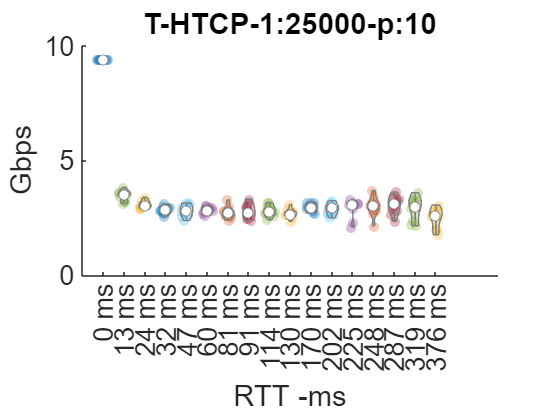

plot_violine(40,testbed_htcp_g_25000_p_ten,celldate_g,'T-HTCP-1:25000-p:10');

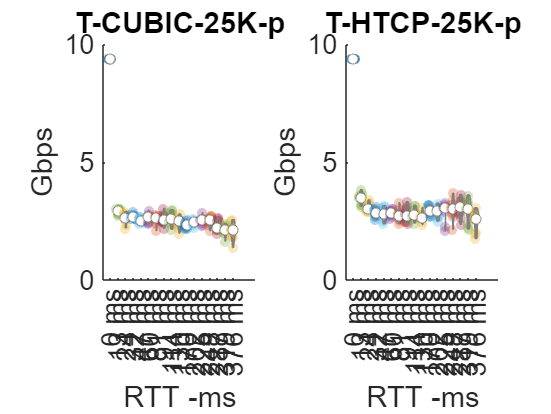


figure(240); clf reset
plot_violine_pair(240,testbed_cubic_g_25000_p_ten,testbed_htcp_g_25000_p_ten,...
celldate_g,celldate_g,...
'T-CUBIC-25K-p','T-HTCP-25K-p');

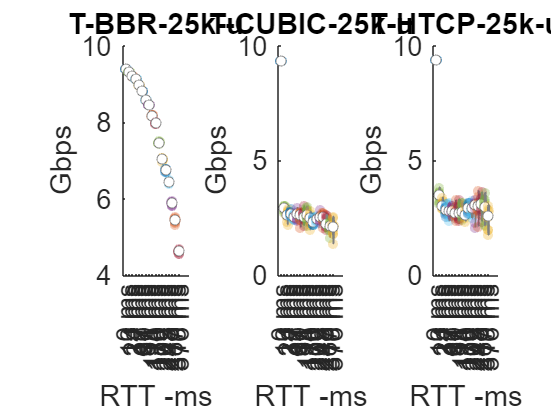


figure(240); clf reset
plot_violine_3(240,testbed_bbr_g_25000_p_ten,testbed_cubic_g_25000_p_ten,testbed_htcp_g_25000_p_ten,...
celldate_g,celldate_g,celldate_g,...
'T-BBR-25k-u','T-CUBIC-25k-u','T-HTCP-25k-u');

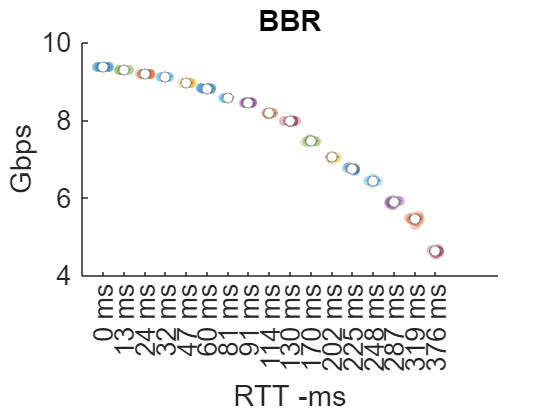


figure(240); clf reset
plot_violine(240,testbed_bbr_g_25000_p_ten,celldate_g,'BBR');

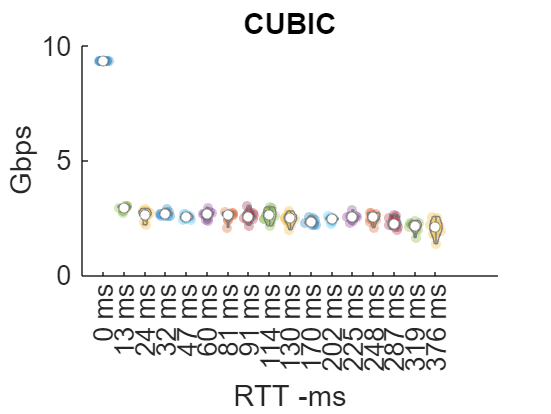


figure(240); clf reset
plot_violine(240,testbed_cubic_g_25000_p_ten,celldate_g,'CUBIC');

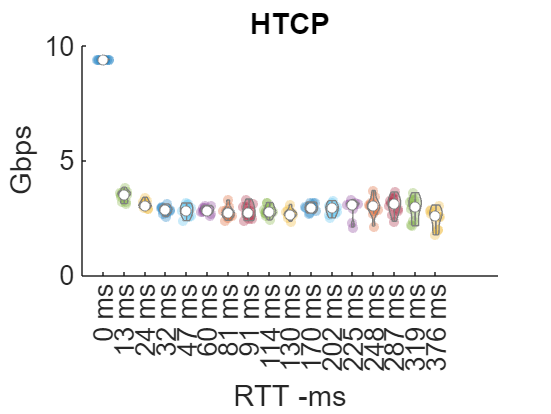


figure(240); clf reset
plot_violine(240,testbed_htcp_g_25000_p_ten,celldate_g,'HTCP');

#### 1 in 500


file_name='iperf3_tcp_log_q1_10gige_limit_500_dist_4_uniform_q2_bbr_updated_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_bbr_1_500_p_single1,testbed_bbr_1_500_p_ten1,testbed_bbr_1_500_p_ten_mean1]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_bbr_1_500_p_single1,testbed_bbr_1_500_p_ten1,celldate_g,celldate_g,'T-BBR-1-500-p:1','T-HH-1-500-p:10');
plot_violine(40,testbed_bbr_1_500_p_ten1,celldate_g,'T-BBR-1-500-p:10');

file_name='iperf3_tcp_log_q1_10gige_limit_500_dist_4_uniform_q2_cubic_updated_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_cubic_1_500_p_single,testbed_cubic_1_500_p_ten,testbed_cubic_1_500_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_cubic_1_500_p_single,testbed_cubic_1_500_p_ten,celldate_g,celldate_g,'T-CUBIC-500-p:1','T-CUBIC-500-p:10');
plot_violine(40,testbed_cubic_1_500_p_ten,celldate_g,'T-CUBIC-500-p:10');

file_name='iperf3_tcp_log_q1_10gige_limit_500_dist_4_uniform_q2_htcp_updated_results';
testbed_dir_name_g=strcat(dir_name,'\',file_name,'\');
[testbed_htcp_1_500_p_single,testbed_htcp_1_500_p_ten,testbed_htcp_1_500_p_ten_mean]=read_data_testbed_txt(rtt_g,testbed_dir_name_g);

figure(140); clf reset
plot_box_pair(40,testbed_htcp_1_500_p_single,testbed_htcp_1_500_p_ten,celldate_g,celldate_g,'T-HTCP-1-500-p:1','T-HH-1-500-p:10');
plot_violine(40,testbed_htcp_1_500_p_ten,celldate_g,'T-HTCP-1-500-p:10');

figure(240); clf reset
plot_violine_3(240,testbed_bbr_1_500_p_ten1,testbed_cubic_1_500_p_ten,testbed_htcp_1_500_p_ten,...
celldate_g,celldate_g,celldate_g,...
'T-BBR-500-u','T-CUBIC-500-u','T-HTCP-500-u');

figure(241); clf reset
plot_violine(240,testbed_bbr_1_500_p_ten1,celldate_g,'BBR');

figure(242); clf reset
plot_violine(240,testbed_cubic_1_500_p_ten,celldate_g,'CUBIC');

figure(242); clf reset
plot_violine(240,testbed_htcp_1_500_p_ten,celldate_g,'HTCP');

### Functions for profile estimation

plotting 

function plot_box_pair(fig_num,box1,box2,rtt1_cell,rtt2_cell,title1,title2)
    figure(fig_num); clf reset
    subplot(1,2,1)
        T=boxchart(transpose(box1)); hold on;
        title(strcat(title1)); hold on;
        xticklabels(rtt1_cell);
        xtickangle(45);
        plot(mean(transpose(box1)),'linewidth',2); hold on
        ylabel('Gbps');
        xlabel('RTT -ms');
        set(gca,'FontSize',16);
           
    subplot(1,2,2)
        T=boxchart(transpose(box2)); hold on;
        title(strcat(title2)); hold on;
        xticklabels(rtt2_cell);
        xtickangle(45);
        plot(mean(transpose(box2)),'linewidth',2); hold on
        ylabel('Gbps');
        xlabel('RTT -ms');
        set(gca,'FontSize',16);
end

function plot_box_pair_profile(fig_num,box1,box2,profile1,profile2,rtt1_cell,rtt2_cell,title1,title2)
    figure(fig_num); clf reset
    subplot(1,2,1)
        T=boxchart(transpose(box1),'linewidth',2); hold on;
        plot(profile1); hold on
        title(strcat(title1)); hold on;
        xticklabels(rtt1_cell);
        xtickangle(45);
        plot(mean(transpose(box1)),'linewidth',2); hold on
        ylabel('Gbps');
        xlabel('RTT -ms');
        set(gca,'FontSize',16);
           
    subplot(1,2,2)
        T=boxchart(transpose(box2)); hold on;
        plot(profile2,'linewidth',2)
        title(strcat(title2)); hold on;
        xticklabels(rtt2_cell);
        xtickangle(45);
        plot(mean(transpose(box2)),'linewidth',2); hold on
        ylabel('Gbps');
        xlabel('RTT -ms');
        set(gca,'FontSize',16);
end

function plot_box(fig_num,box1,rtt1_cell,title1)
    figure(fig_num); clf reset
    T=boxchart(transpose(box1)); hold on;
    title(strcat(title1)); hold on;
    xticklabels(rtt1_cell);
    xtickangle(45);
    ylabel('Gbps');
    xlabel('RTT -ms');
    set(gca,'FontSize',16);
end

function plot_violine_pair(fig_num,box1,box2,rtt1_cell,rtt2_cell,title1,title2)
    figure(fig_num); clf reset
    subplot(1,2,1)
        T=violinplot(transpose(box1)); hold on;
        title(strcat(title1)); hold on;
        set(gca,'XTick',1:length(rtt1_cell),'XTickLabel',rtt1_cell);
        ylabel('Gbps');
        xlabel('RTT -ms');
        set(gca,'FontSize',16);
            
    subplot(1,2,2)
        T=violinplot(transpose(box2)); hold on;
        title(strcat(title2)); hold on;
        set(gca,'XTick',1:length(rtt2_cell),'XTickLabel',rtt2_cell);
        ylabel('Gbps');
        xlabel('RTT -ms');
        set(gca,'FontSize',16);
end

function plot_violine_3(fig_num,box1,box2,box3,rtt1_cell,rtt2_cell,rtt3_cell,title1,title2,title3)
    figure(fig_num); clf reset
    subplot(1,3,1)
        T=violinplot(transpose(box1)); hold on;
        title(strcat(title1)); hold on;
        set(gca,'XTick',1:length(rtt1_cell),'XTickLabel',rtt1_cell);
        ylabel('Gbps');
        xlabel('RTT -ms');
        set(gca,'FontSize',16);
            
    subplot(1,3,2)
        T=violinplot(transpose(box2)); hold on;
        title(strcat(title2)); hold on;
        set(gca,'XTick',1:length(rtt2_cell),'XTickLabel',rtt2_cell);
        ylabel('Gbps');
        xlabel('RTT -ms');
        set(gca,'FontSize',16);
subplot(1,3,3)
        T=violinplot(transpose(box3)); hold on;
        title(strcat(title3)); hold on;
        set(gca,'XTick',1:length(rtt3_cell),'XTickLabel',rtt3_cell);
        ylabel('Gbps');
        xlabel('RTT -ms');
        set(gca,'FontSize',16);
end
function plot_violine(fig_num,box1,rtt1_cell,title1)
    figure(fig_num); clf reset
    T=violinplot(transpose(box1)); hold on;
    title(strcat(title1)); hold on;
    set(gca,'XTick',1:length(rtt1_cell),'XTickLabel',rtt1_cell);
    ylabel('Gbps');
    xlabel('RTT -ms');
    set(gca,'FontSize',16);
end

function plot_violine_mean(fig_num,box1,box1_mean,rtt1_cell,title1)
    figure(fig_num); clf reset
    T=violinplot(transpose(box1)); hold on;
    plot(box1_mean,'LineWidth',3); hold on
    title(strcat(title1)); hold on;
    set(gca,'XTick',1:length(rtt1_cell),'XTickLabel',rtt1_cell);
    ylabel('Gbps');
    xlabel('RTT -ms');
    set(gca,'FontSize',16);
end


Reading data


function [single,ten,ten_mean]=read_data(rtt,tcp_str,dir)
    for i=1:length(rtt)
        data_file=strcat('tcp_file_iperf_',tcp_str,'_10g_',int2str(rtt(i)),'ms.txt');
    
        input_file=strcat(dir,data_file);
        [bin1,bin2,bin3,bin4,bin5,bin6,bin7,bin8,bin9,bin10]=textread(input_file,'%f %f %f %f %f %f %f %f %f %f');
        bin_mesh=[bin1,bin2,bin3,bin4,bin5,bin6,bin7,bin8,bin9,bin10];
    
        single(i,:)=bin_mesh(1,:);
        ten(i,:)=bin_mesh(10,:);
        ten_mean(i)=mean(ten(i,:));
    
    end
end

function [single,ten,ten_mean]=read_data_testbed(rtt,dir)
    for i=1:length(rtt)
        data_file=strcat('tcp_file_',int2str(rtt(i)));
    
        input_file=strcat(dir,data_file);
        [bin1,bin2,bin3,bin4,bin5,bin6,bin7,bin8,bin9,bin10]=textread(input_file,'%f %f %f %f %f %f %f %f %f %f');
        bin_mesh=[bin1,bin2,bin3,bin4,bin5,bin6,bin7,bin8,bin9,bin10];
    
        single(i,:)=bin_mesh(1,:);
        ten(i,:)=bin_mesh(10,:);
        ten_mean(i)=mean(ten(i,:));
    
    end
end

function [single,ten,ten_mean]=read_data_testbed_txt(rtt,dir)
    for i=1:length(rtt)
        data_file=strcat('tcp_file_',int2str(rtt(i)),'.txt');
    
        input_file=strcat(dir,data_file);
        [bin1,bin2,bin3,bin4,bin5,bin6,bin7,bin8,bin9,bin10]=textread(input_file,'%f %f %f %f %f %f %f %f %f %f');
        bin_mesh=[bin1,bin2,bin3,bin4,bin5,bin6,bin7,bin8,bin9,bin10];
    
        single(i,:)=bin_mesh(1,:);
        ten(i,:)=bin_mesh(10,:);
        ten_mean(i)=mean(ten(i,:));
    
    end
end

function [single,ten,ten_mean]=read_src_testbed_txt(rtt,dir)
    for i=1:length(rtt)
        data_file=strcat('src_rate_',int2str(rtt(i)),'.txt');
    
        input_file=strcat(dir,data_file);
        [bin1,bin2,bin3,bin4,bin5,bin6,bin7,bin8,bin9,bin10]=textread(input_file,'%f %f %f %f %f %f %f %f %f %f');
        bin_mesh=[bin1,bin2,bin3,bin4,bin5,bin6,bin7,bin8,bin9,bin10];
    
        single(i,:)=bin_mesh(1,:);
        ten(i,:)=bin_mesh(10,:);
        ten_mean(i)=mean(ten(i,:));
    
    end
end

function [single,ten,ten_mean]=read_retran_testbed_txt(rtt,dir)
    for i=1:length(rtt)
        data_file=strcat('retransmissions_',int2str(rtt(i)),'.txt');
    
        input_file=strcat(dir,data_file);
        [bin1,bin2,bin3,bin4,bin5,bin6,bin7,bin8,bin9,bin10]=textread(input_file,'%f %f %f %f %f %f %f %f %f %f');
        bin_mesh=[bin1,bin2,bin3,bin4,bin5,bin6,bin7,bin8,bin9,bin10];
    
        single(i,:)=bin_mesh(1,:);
        ten(i,:)=bin_mesh(10,:);
        ten_mean(i)=mean(ten(i,:));
    
    end
end